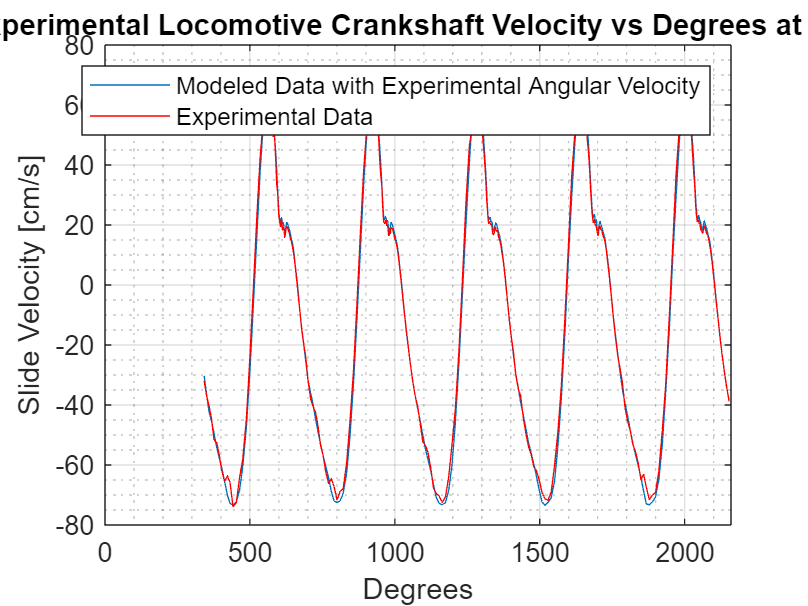

clc
close all

format bank

% Constants
r = 7.5; %[cm]
d = 15.5; %[cm]
l = 26; %[cm]

% lcsdata Function Call
[theta_5pt5,w_5pt5,v_5pt5,t_5pt5] = lcsdata('Locomotive_Data_2020\Test1_5pt5V');
[theta_6pt5,w_6pt5,v_6pt5,t_6pt5] = lcsdata('Locomotive_Data_2020\Test1_6pt5V');
[theta_7pt5,w_7pt5,v_7pt5,t_7pt5] = lcsdata('Locomotive_Data_2020\Test1_7pt5V');
[theta_8pt5,w_8pt5,v_8pt5,t_8pt5] = lcsdata('Locomotive_Data_2020\Test1_8pt5V');
[theta_9pt5,w_9pt5,v_9pt5,t_9pt5] = lcsdata('Locomotive_Data_2020\Test1_9pt5V');
[theta_10pt5,w_10pt5,v_10pt5,t_10pt5] = lcsdata('Locomotive_Data_2020\Test1_10pt5V');

% Plots
% 5.5V
plot(theta_5pt5,v_5pt5) 
xlabel('Degrees')
ylabel('Slide Velocity [cm/s]')
grid on; grid minor
xlim([0 2160])
title('Experimental Locomotive Crankshaft Velocity vs Degrees at 5.5V')
hold on

[~,vb_j] = lcsmodel(r,d,l,theta_5pt5,w_5pt5);

plot(theta_5pt5,vb_j,'-r')
legend('Modeled Data with Experimental Angular Velocity','Experimental Data')
hold off

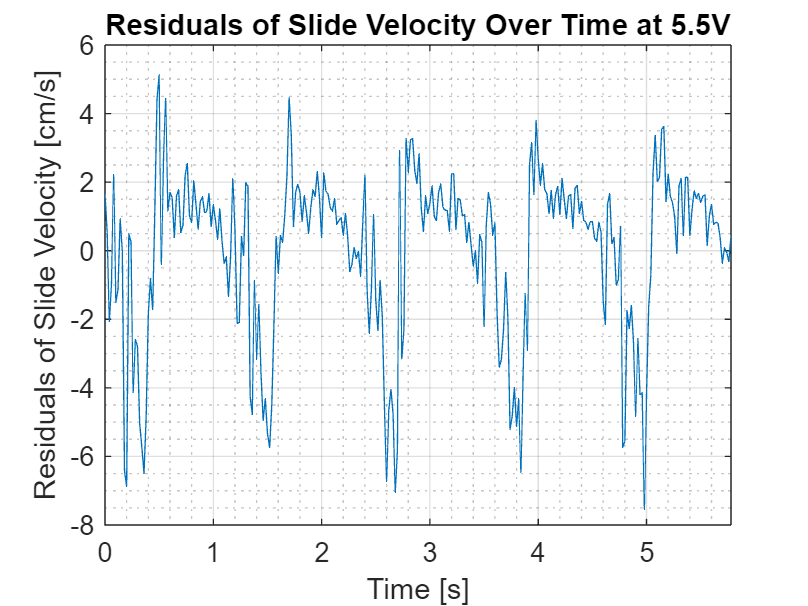


residuals_5pt5 = v_5pt5 - vb_j;

plot(t_5pt5,residuals_5pt5)
xlim([0 t_5pt5(end)])
xlabel('Time [s]')
ylabel('Residuals of Slide Velocity [cm/s]')
grid on; grid minor
title('Residuals of Slide Velocity Over Time at 5.5V')


% Mean and STD with Outliers
mean_5pt5 = mean(residuals_5pt5)

mean_5pt5 =           0.00


std_5pt5 = std(residuals_5pt5)

std_5pt5 =           2.44



% Remove Outliers
residuals2_5pt5 = rmoutliers(residuals_5pt5);

% Mean and STD without Outliers
mean2_5pt5 = mean(residuals2_5pt5)

mean2_5pt5 =           0.69


std2_5pt5 = std(residuals2_5pt5)

std2_5pt5 =           1.58


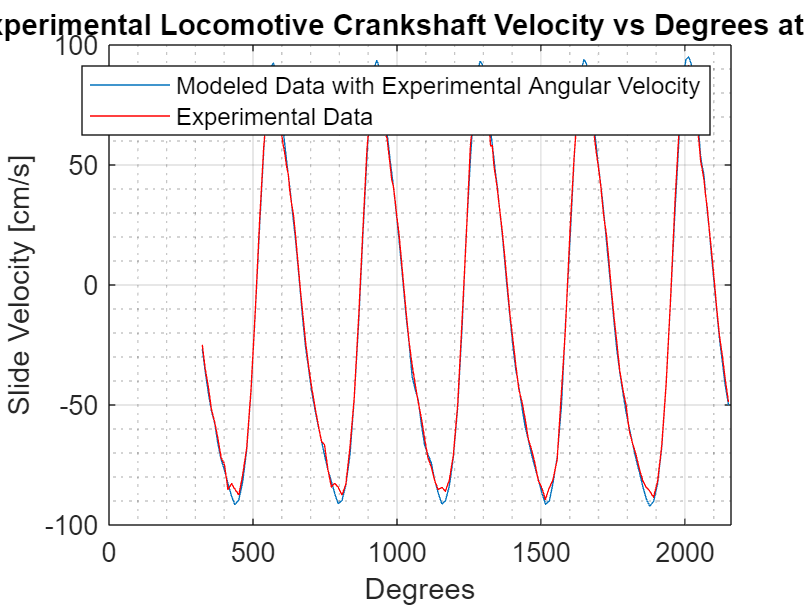


% 6.5V
plot(theta_6pt5,v_6pt5)
xlabel('Degrees')
ylabel('Slide Velocity [cm/s]')
grid on; grid minor
xlim([0 2160])
title('Experimental Locomotive Crankshaft Velocity vs Degrees at 6.5V')
hold on

[~,vb_j] = lcsmodel(r,d,l,theta_6pt5,w_6pt5);

plot(theta_6pt5,vb_j,'-r')
legend('Modeled Data with Experimental Angular Velocity','Experimental Data')
hold off

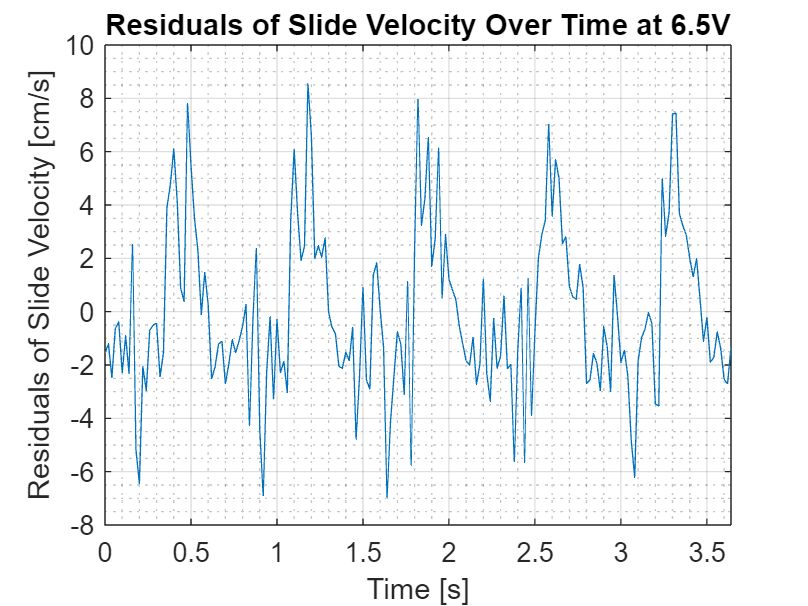


residuals_6pt5 = v_6pt5 - vb_j;

plot(t_6pt5,residuals_6pt5)
xlim([0 t_6pt5(end)])
xlabel('Time [s]')
ylabel('Residuals of Slide Velocity [cm/s]')
grid on; grid minor
title('Residuals of Slide Velocity Over Time at 6.5V')


% Mean and STD
mean_6pt5 = mean(residuals_6pt5)

mean_6pt5 =          -0.04


std_6pt5 = std(residuals_6pt5)

std_6pt5 =           3.10



% Remove Outliers
residuals2_6pt5 = rmoutliers(residuals_6pt5);

% Mean and STD without Outliers
mean2_6pt5 = mean(residuals2_6pt5)

mean2_6pt5 =          -0.17


std2_6pt5 = std(residuals2_6pt5)

std2_6pt5 =           2.93


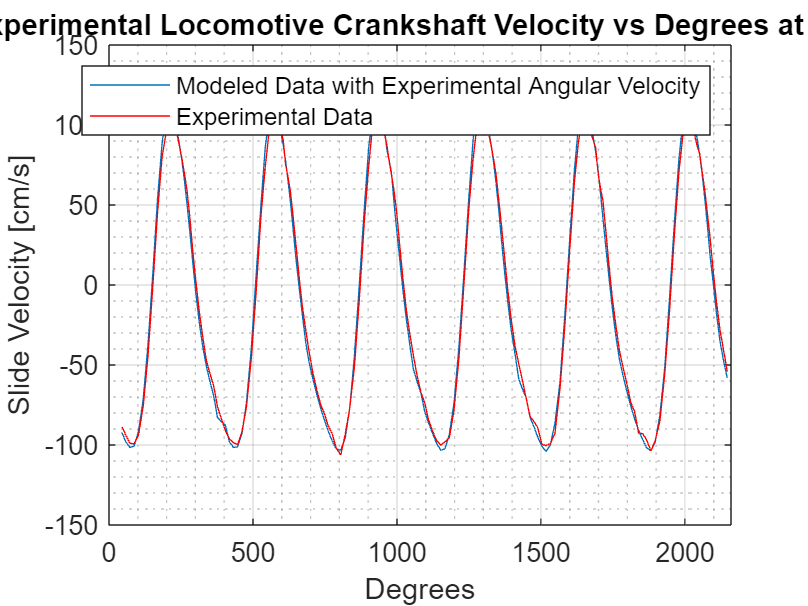


% 7.5V
plot(theta_7pt5,v_7pt5)
xlabel('Degrees')
ylabel('Slide Velocity [cm/s]')
grid on; grid minor
xlim([0 2160])
title('Experimental Locomotive Crankshaft Velocity vs Degrees at 7.5V')
hold on

[~,vb_j] = lcsmodel(r,d,l,theta_7pt5,w_7pt5);

plot(theta_7pt5,vb_j,'-r')
legend('Modeled Data with Experimental Angular Velocity','Experimental Data')
hold off

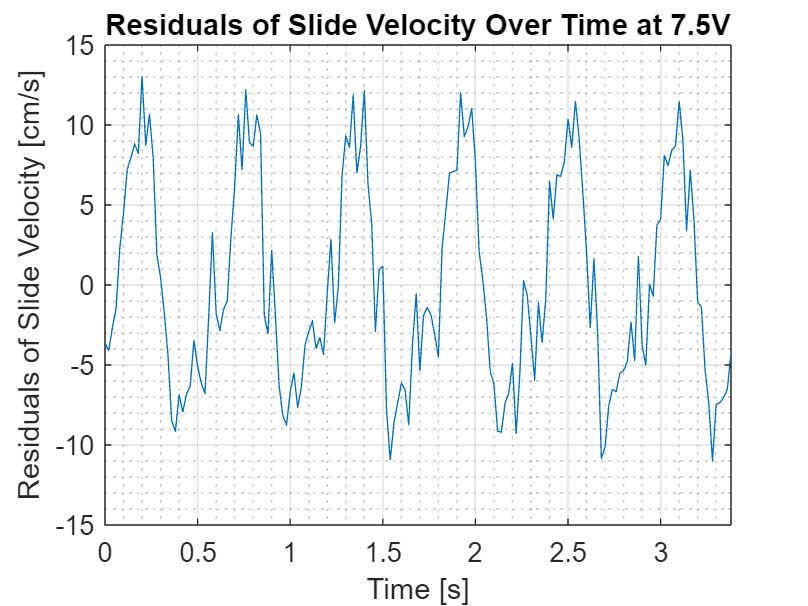


residuals_7pt5 = v_7pt5 - vb_j;

plot(t_7pt5,residuals_7pt5)
xlim([0 t_7pt5(end)])
xlabel('Time [s]')
ylabel('Residuals of Slide Velocity [cm/s]')
grid on; grid minor
title('Residuals of Slide Velocity Over Time at 7.5V')


% Mean and STD
mean_7pt5 = mean(residuals_7pt5)

mean_7pt5 =           0.05


std_7pt5 = std(residuals_7pt5)

std_7pt5 =           6.49



% Remove Outliers
residuals2_7pt5 = rmoutliers(residuals_7pt5);

% Mean and STD without Outliers
mean2_7pt5 = mean(residuals2_7pt5)

mean2_7pt5 =           0.05


std2_7pt5 = std(residuals2_7pt5)

std2_7pt5 =           6.49


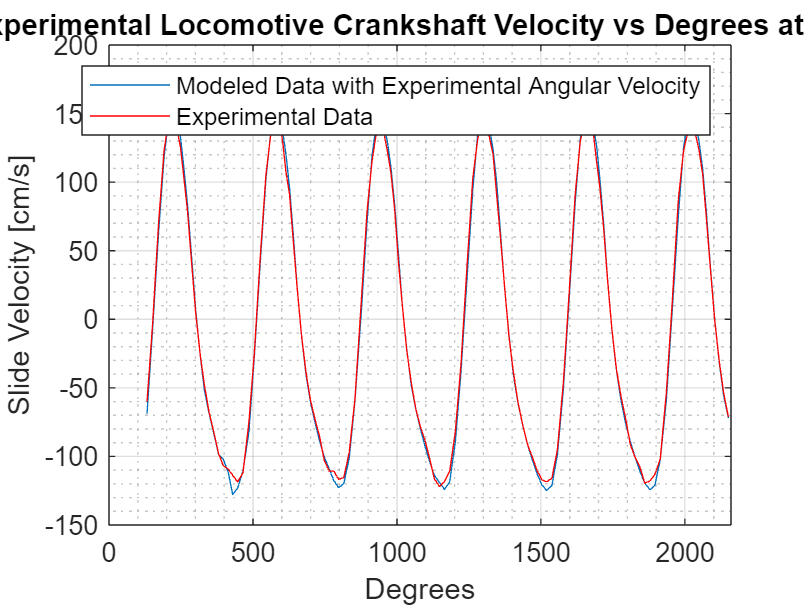


% 8.5V
plot(theta_8pt5,v_8pt5)
xlabel('Degrees')
ylabel('Slide Velocity [cm/s]')
grid on; grid minor
xlim([0 2160])
title('Experimental Locomotive Crankshaft Velocity vs Degrees at 8.5V')
hold on

[~,vb_j] = lcsmodel(r,d,l,theta_8pt5,w_8pt5);

plot(theta_8pt5,vb_j,'-r')
legend('Modeled Data with Experimental Angular Velocity','Experimental Data')
hold off

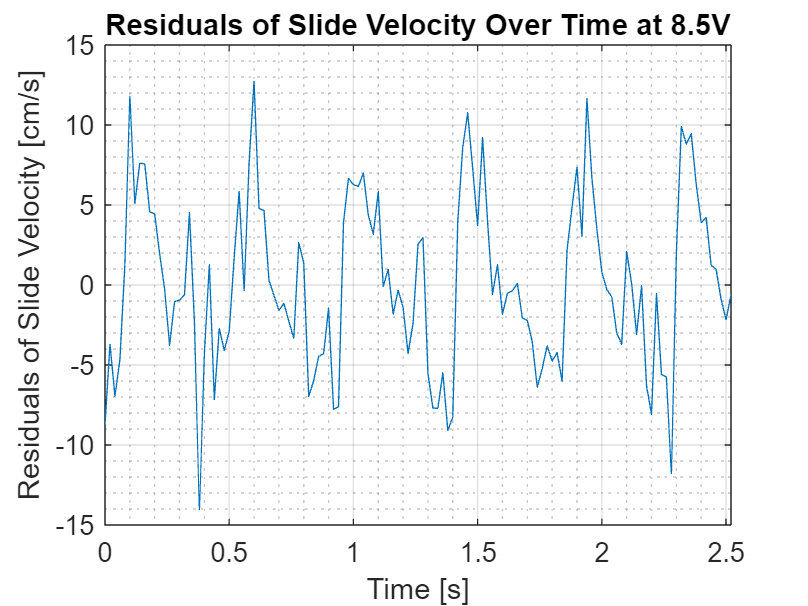


residuals_8pt5 = v_8pt5 - vb_j;

plot(t_8pt5,residuals_8pt5)
xlim([0 t_8pt5(end)])
xlabel('Time [s]')
ylabel('Residuals of Slide Velocity [cm/s]')
grid on; grid minor
title('Residuals of Slide Velocity Over Time at 8.5V')


% Mean and STD
mean_8pt5 = mean(residuals_8pt5)

mean_8pt5 =           0.12


std_8pt5 = std(residuals_8pt5)

std_8pt5 =           5.32



% Remove Outliers
residuals2_8pt5 = rmoutliers(residuals_8pt5);

% Mean and STD without Outliers
mean2_8pt5 = mean(residuals2_8pt5)

mean2_8pt5 =           0.12


std2_8pt5 = std(residuals2_8pt5)

std2_8pt5 =           5.32


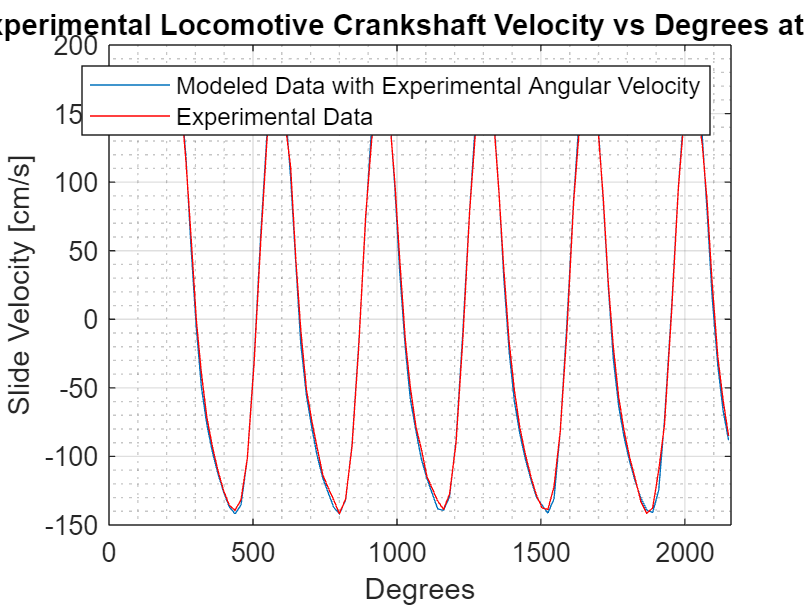


% 9.5V
plot(theta_9pt5,v_9pt5)
xlabel('Degrees')
ylabel('Slide Velocity [cm/s]')
grid on; grid minor
xlim([0 2160])
title('Experimental Locomotive Crankshaft Velocity vs Degrees at 9.5V')
hold on

[~,vb_j] = lcsmodel(r,d,l,theta_9pt5,w_9pt5);

plot(theta_9pt5,vb_j,'-r')
legend('Modeled Data with Experimental Angular Velocity','Experimental Data')
hold off

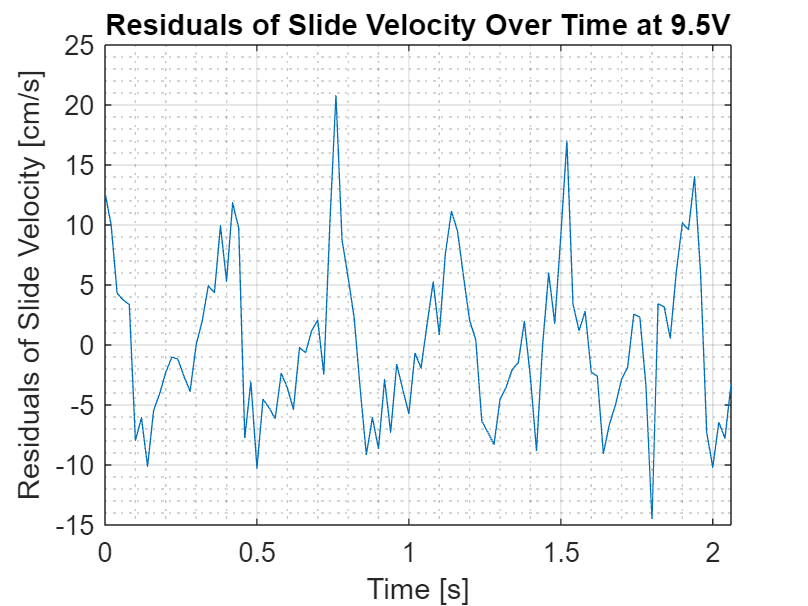


residuals_9pt5 = v_9pt5 - vb_j;

plot(t_9pt5,residuals_9pt5)
xlim([0 t_9pt5(end)])
xlabel('Time [s]')
ylabel('Residuals of Slide Velocity [cm/s]')
grid on; grid minor
title('Residuals of Slide Velocity Over Time at 9.5V')


% Mean and STD
mean_9pt5 = mean(residuals_9pt5)

mean_9pt5 =           0.03


std_9pt5 = std(residuals_9pt5)

std_9pt5 =           6.61



% Remove Outliers
residuals2_9pt5 = rmoutliers(residuals_9pt5);

% Mean and STD without Outliers
mean2_9pt5 = mean(residuals2_9pt5)

mean2_9pt5 =          -0.17


std2_9pt5 = std(residuals2_9pt5)

std2_9pt5 =           6.32


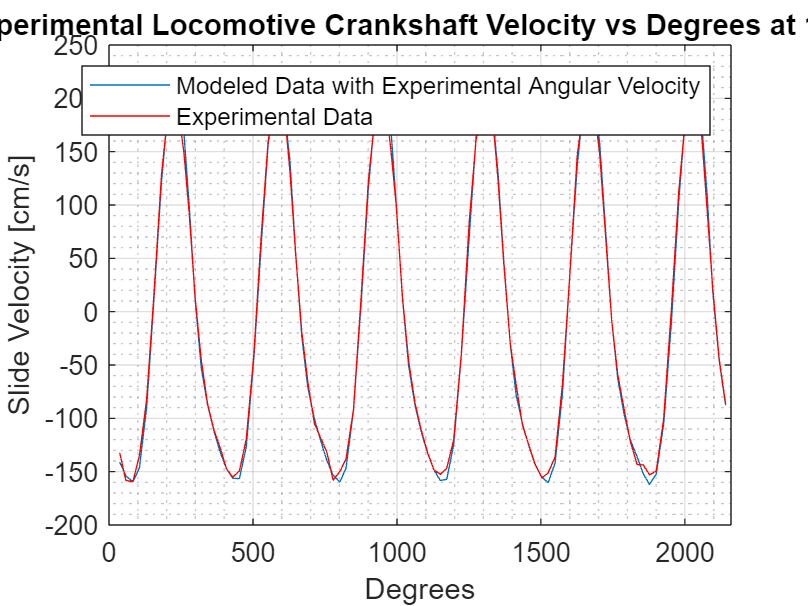


% 10.5V
plot(theta_10pt5,v_10pt5)
xlabel('Degrees')
ylabel('Slide Velocity [cm/s]')
grid on; grid minor
xlim([0 2160])
title('Experimental Locomotive Crankshaft Velocity vs Degrees at 10.5V')
hold on

[~,vb_j] = lcsmodel(r,d,l,theta_10pt5,w_10pt5);

plot(theta_10pt5,vb_j,'-r')
legend('Modeled Data with Experimental Angular Velocity','Experimental Data')
hold off

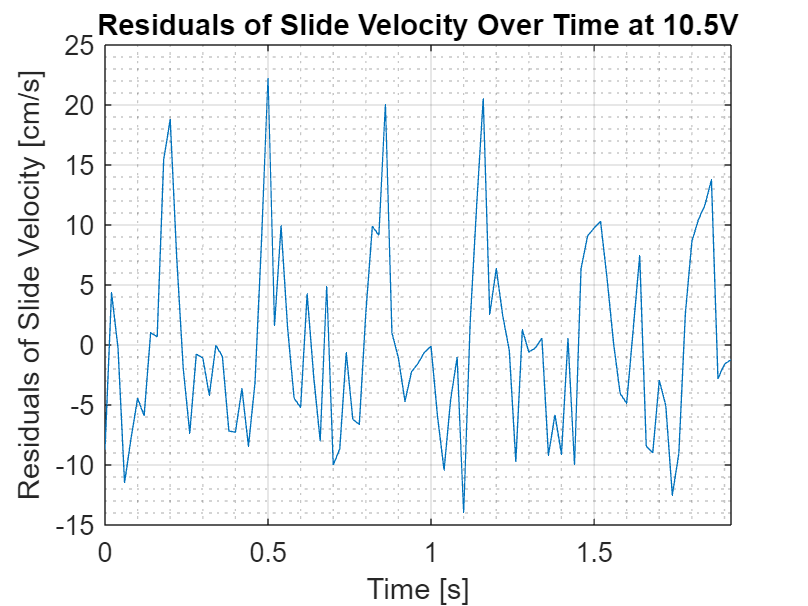


residuals_10pt5 = v_10pt5 - vb_j;

plot(t_10pt5,residuals_10pt5)
xlim([0 t_10pt5(end)])
xlabel('Time [s]')
ylabel('Residuals of Slide Velocity [cm/s]')
grid on; grid minor
title('Residuals of Slide Velocity Over Time at 10.5V')


% Mean and STD
mean_10pt5 = mean(residuals_10pt5)

mean_10pt5 =          -0.02


std_10pt5 = std(residuals_10pt5)

std_10pt5 =           7.74



% Remove Outliers
residuals2_10pt5 = rmoutliers(residuals_10pt5);

% Mean and STD without Outliers
mean2_10pt5 = mean(residuals2_10pt5)

mean2_10pt5 =          -0.25


std2_10pt5 = std(residuals2_10pt5)

std2_10pt5 =           7.43


function [vb_i,vb_j] = lcsmodel(r,d,l,theta,w)

% Derivated Equations
beta = asind((d - r .* sind(theta))/l);
vb_i = (w .* l .* cosd(beta)) - (w .* r .* cosd(theta));
vb_j = -r .* w .* sind(theta) - r .* w .* cosd(theta) .* tand(beta);

end

function [theta_exp,w_exp,v_exp,time] = lcsdata(filename)

% Load and Break Apart Data
lcs_data = load(filename);
time = lcs_data(:,1);
theta_exp = lcs_data(:,2);
w_exp = lcs_data(:,4);
v_exp = lcs_data(:,5);

% Conversions
v_exp = v_exp * 0.1; %[mm/s --> cm/s]
w_exp = w_exp .* (pi/180); %[deg/s --> rad/s]

% Start At 0 Degrees
theta_exp = theta_exp/360; % convert to revolutions
theta_exp = theta_exp - fix(theta_exp(1)); % zero out
theta_exp = theta_exp*360; % re-convert to degrees

% End After 6 Revolutions
for i = 1:length(time)
    if theta_exp(i) > 2160
        theta_exp(i) = NaN;
        time(i) = NaN;
        w_exp(i) = NaN;
        v_exp(i) = NaN;
    end
end

% Remove NaN
theta_exp = rmmissing(theta_exp)';
time = rmmissing(time)';
w_exp = rmmissing(w_exp)';
v_exp = rmmissing(v_exp)';

end